# Diferenciación e integración numérica

## Diferenciación numérica para la segunda derivada

f = @(x) exp(x) .* cos(x);
xi = 1;

fvalue=f(1)

fvalue = 1.4687


h=1 ./ 2 .^ [1:5];
d2f_value = ( f(xi+h) - 2 * f(xi*ones(size(h))) + f(xi-h) ) ./ (h .^ 2)

d2f_value =    -4.6939   -4.6051   -4.5823   -4.5766   -4.5752



syms x
d2f_exacto = double(subs(diff(f(x),x,2),x,xi))

d2f_exacto = -4.5747

d2f_error = abs(d2f_value - d2f_exacto)

d2f_error =     0.1192    0.0304    0.0076    0.0019    0.0005


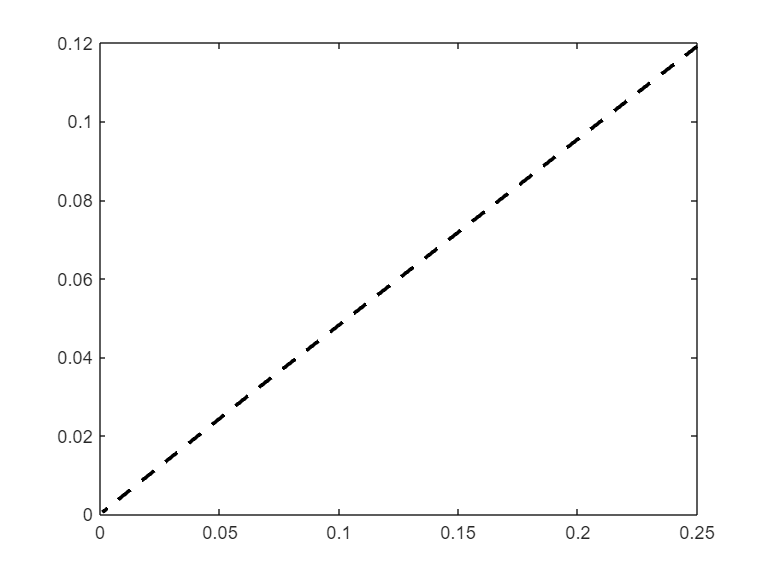


plot(h .^ 2, d2f_error, 'k--', 'LineWidth',2)

## Método de Trapecio Compuesto

% Fórmula del trapecio compuesto}
h=0.75

h = 0.7500

xi=0:h:3;
yi=[0 0.51 1.5 1.75 0.42];
Ivalue = (h / 2) * (yi(1) + 2 * sum(yi(2:end-1)) + yi(end))

Ivalue = 2.9775


syms a
yi=[0 0.51 a 1.75 0.42];

% Fórmula del trapecio compuesto
I = (h / 2) * (yi(1) + 2 * sum(yi(2:end-1)) + yi(end))

$$I = \frac{3\,a}{4}+\frac{741}{400}$$

avalue = double(solve(I == 3.21))

avalue = 1.8100


% Usando trapz
xi=0:h:3;
yi=[0 0.51 avalue 1.75 0.42];
Itrapz = trapz(xi,yi)

Itrapz = 3.2100

## [Integración de Romberg](https://grader.mathworks.com/courses/154085-modulo-de-autoaprendizaje-2024-2/assignments/453785-diferenciacion-e-integracion-numerica/problems/1687635-integracion-de-romberg)

% Datos
xi = [0, 2, 4, 6, 8, 10, 12, 14, 16, 18, 20]; % Profundidad (m)
yi = [1000, 1200, 1800, 2400, 3000, 4000, 5500, 7000, 9000, 12000, 16000]; % Área (m²)

% Ajustar un polinomio de grado 5 a los datos
[p, S] = polyfit(xi, yi, 5)

p =     0.0070   -0.2304    3.4036   -2.1671  154.5134  973.0769


S = struct with fields:
        R: [6×6 double]
       df: 5
    normr: 267.9021



% Definir la función ajustada
f= @(x) p(1)*x.^5+p(2)*x.^4+p(3)*x.^3+p(4)*x.^2+p(5)*x+p(6)

f = function_handle with value:
    @(x)p(1)*x.^5+p(2)*x.^4+p(3)*x.^3+p(4)*x.^2+p(5)*x+p(6)



% Evaluando f(5)
fvalue = f(5)

fvalue = 1.9948e+03


% Romberg
TablaRomberg=Romberg(f,0,20,4)

TablaRomberg = 1.0e+05 *

    1.6976    1.1129    1.0808    1.0808
    1.2590    1.0828    1.0808         0
    1.1269    1.0809         0         0
    1.0924         0         0         0


VolumenRomberg=TablaRomberg(1,4)

VolumenRomberg = 1.0808e+05


% Trapecio compuesto
VolumenTrapecio = trapz(xi,yi)

VolumenTrapecio = 108800

## [Cuadratura Gaussiana](https://grader.mathworks.com/courses/154085-modulo-de-autoaprendizaje-2024-2/assignments/453785-diferenciacion-e-integracion-numerica/problems/1687630-cuadratura-gaussiana)

% Parámetros del problema
m = 0.8; % kg
b = 0.4; % m
mu = 0.3;
k = 80; % N/m
g = 9.81; % m/s^2

% Definición de la función f(x)
f = @(x) mu * g + (k / m) * (mu * b + x).*(1 - b ./ sqrt(b^2 + x.^2));

%% 1. Determinar el valor de v0 usando el comando int de MATLAB
syms x
integral_exacta = int(f(x), x, 0, b);
iexac = double(integral_exacta)

iexac = 3.1192

% Valor exacto de v0 (v_exac)
v_exac = sqrt(2 * iexac)

v_exac = 2.4977


%% 2. Utilizar la cuadratura gaussiana de 3 puntos para encontrar el valor de v0
igauss = gauss(f, 0, b, 3)

igauss = 3.1191

% Valor de v0 por cuadratura gaussiana con 3 puntos (v_gauss)
v_gauss = sqrt(2 * igauss)

v_gauss = 2.4976


%% 3. Determinar el error relativo porcentual de la aproximación con 3 puntos (ErrorG1):
ErrorG1 = (abs(v_exac - v_gauss) / abs(v_exac)) * 100

ErrorG1 = 0.0013


%% 4. Determinar el error relativo porcentual de la aproximación con 7 puntos en la cuadratura gaussiana
igauss7 = gauss(f, 0, b, 7)

igauss7 = 3.1192

v_gauss7 = sqrt(2 * igauss7)

v_gauss7 = 2.4977

ErrorG2 = (abs(v_exac - v_gauss7) / abs(v_exac)) * 100

ErrorG2 = 8.2951e-09

Funciones usadas

function I=trapecomp(f,a,b,h)
xnodos=[a:h:b];
I=(h/2)*(f(a)+2*sum(f(xnodos(2:end-1)))+f(b));
end

function I=Romberg(f,a,b,N)
% N: Nivel
I=zeros(N,N);
for j=1:N
    h=(b-a)/2^(j-1);
    I(j,1)=trapecomp(f,a,b,h);
end
for k=2:N
    for j=1:N-k+1
        I(j,k)=(4^(k-1)*I(j+1,k-1)-I(j,k-1))/(4^(k-1)-1);
    end
end
end

function I = gauss(f, a, b, n)
% n: número de puntos
    syms x
    lg = legendreP(n, x);
    dlg = matlabFunction(diff(lg, x));
    roots = double(solve(lg == 0));
    pesos = (2 ./ ((1 - roots.^2) .* dlg(roots).^2));

    syms t
    x = ((b - a) * t + (a + b)) / 2;
    F = matlabFunction(f(x));
    I = ((b - a) / 2) * sum(pesos .* (F(roots)));
end